# GEOPH 522 - Data Analysis & Geostatistics

# HW #1

# Cameron Carsley

# 9/4/2018

## Load data into MATLAB using the *load *command

D1 = load('depths1.txt');                                % load depths1 data into Matlab and set to variable D1
D2 = load('depths2.txt');                                % load depths2 data into Matlab and set to variable D2
D = [D1 D2];                                             % concatonate D1 & D2, saving steps

## 1. For each dataset, calculate and report the mean and standard deviation (use mean.m, std.m) 

meanD = mean(D);                                             % calculate mean of D arrays
fprintf('The mean of Depth 1 is %.2f cm.', meanD(1))         % display mean of D1

The mean of Depth 1 is 203.18 cm.

fprintf('The mean of Depth 2 is %.2f cm.', meanD(2))         % display mean of D2

The mean of Depth 2 is 201.81 cm.


stdD = std(D);                                                     % calculate std of D arrays
fprintf('The standard deviation of Depth 1 is %.2f cm.', stdD(1))  % print std of d1 

The standard deviation of Depth 1 is 69.85 cm.

fprintf('The standard deviation of Depth 2 is %.2f cm.', stdD(2))  % print std of d2

The standard deviation of Depth 2 is 73.01 cm.

## 2. For each dataset, calculate and report the median, mode, IQR, skewness, and kurtosis. 

medD = median(D);                                      % calculate median of D arrays
fprintf('The median of Depth 1 is %.2f cm.', medD(1))  % display median of D1

The median of Depth 1 is 203.47 cm.

fprintf('The median of Depth 2 is %.2f cm.', medD(2))  % display median of D1

The median of Depth 2 is 188.70 cm.


modeD = mode(D);                                       % calculate mode of D arrays
fprintf('The mode of Depth 1 is %.2f cm.', modeD(1))   % display mode of D1

The mode of Depth 1 is 0.92 cm.

fprintf('The mode of Depth 2 is %.2f cm.', modeD(2))   % display mode of D1

The mode of Depth 2 is 101.85 cm.


iqrD = iqr(D);                                         % calculate IQR of D arrays
fprintf('The IQR of Depth 1 is %.2f cm.', iqrD(1))     % display IQR of D1

The IQR of Depth 1 is 93.89 cm.

fprintf('The IQR of Depth 2 is %.2f cm.', iqrD(2))     % display IQR of D1

The IQR of Depth 2 is 143.05 cm.


skewD = skewness(D);                                   % calculate skewness of D arrays
fprintf('The skewness of Depth 1 is %.2f', skewD(1))  % display skewness of D1

The skewness of Depth 1 is 0.07

fprintf('The skewness of Depth 2 is %.2f', skewD(2))  % display skewness of D1

The skewness of Depth 2 is 0.05


kurtD = kurtosis(D);                                   % calculate kurtosis of D arrays
fprintf('The kurtosis of Depth 1 is %.2f', kurtD(1))  % display kurtosis of D1

The kurtosis of Depth 1 is 2.94

fprintf('The kurtosis of Depth 2 is %.2f', kurtD(2))  % display kurtosis of D1

The kurtosis of Depth 2 is 1.14

## 3. For each dataset, use the boxplot.m function to create a notched boxplot. 

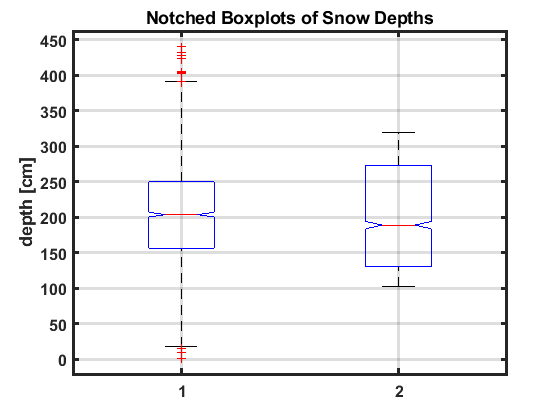

figure(1); clf                                                   % initiate figure and clear it (clf) for boxplot comparing depths
boxplot(D, 'notch', 'on');                                       % create boxplot of datasets with notches on
grid on                                                          % turn on grid to see if notches are aligned
set(gca, 'fontsize', 12, 'fontweight', 'bold', 'linewidth', 2);  % set current axes font sizes, weights, and widths
ylabel('depth [cm]')                                             % give plot a y label
title('Notched Boxplots of Snow Depths')                         % give plot a title

## 4. Using the hist.m function, create a histogram of each dataset, using 30 bins.

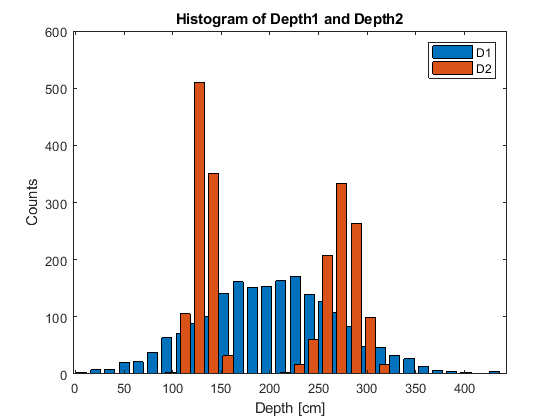

num_bins = 30;                            % # of bins in histogram
[Nc, xbins] = hist(D, num_bins);          % create histogram of D1 with 30 bins

figure(2); clf                            % new figure, clear fig2
bar(xbins, Nc, 'barwidth', 2.5)           % create bar plot of xbins and number of counts, make bar widths wider
title('Histogram of Depth1 and Depth2')   % title plot
xlabel('Depth [cm]')                      % give plot x label            
ylabel('Counts')                          % give plot y label
legend('D1', 'D2')                        % give plot a legend

## 5. Using the subplot.m function, create one figure showing all 4 plots from above.

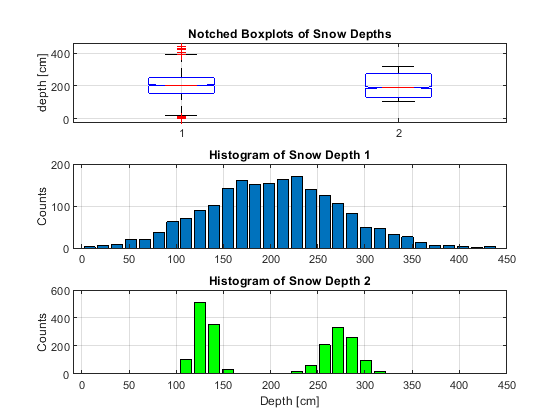

figure(3); clf                               % new figure, cleared for 1 plot with all plots on it
subplot(3,1,1)                               % create plot with 2 subplots, this is #1
boxplot(D, 'notch', 'on');                   % create boxplot of datasets with notches on
grid on                                      % turn on grid to see if notches are aligned
ylabel('depth [cm]')                         % give plot a y label
title('Notched Boxplots of Snow Depths')     % give plot a title

subplot(3,1,2)                               % create 1 plot with 2 subplots, #2
[Nc, xbins] = hist(D, num_bins);             % create histogram of D1 with 30 bins
bar(xbins, Nc(:, 1))                         % create bar plot of xbins and number of counts, make bar widths wider
grid on
title('Histogram of Snow Depth 1')      % title plot
%xlabel('Depth [cm]')                         % give plot x label            
ylabel('Counts')                             % give plot y label
%axis([0 450 0 550])                          % give all subplots the same defined axis

subplot(3,1,3)                               % create 1 plot with 2 subplots, #3
[Nc, xbins] = hist(D, num_bins);             % create histogram of D1 with 30 bins
bar(xbins, Nc(:, 2), 'FaceColor', 'g')              % create bar plot of xbins and number of counts, make bar widths wider
grid on
title('Histogram of Snow Depth 2')      % title plot
xlabel('Depth [cm]')                         % give plot x label            
ylabel('Counts')                             % give plot y label

%axis([0 450 0 550])                          % give all subplots the same defined axis

## 6. Use the axis.m function to set the axis limits to the same range of values for all 4 plots

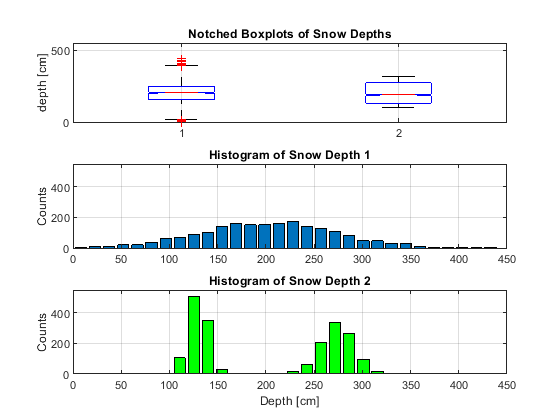

figure(3); clf                               % new figure, cleared for 1 plot with all plots on it
subplot(3,1,1)                               % create plot with 2 subplots, this is #1
boxplot(D, 'notch', 'on');                   % create boxplot of datasets with notches on
grid on                                      % turn on grid to see if notches are aligned
ylabel('depth [cm]')                         % give plot a y label
title('Notched Boxplots of Snow Depths')     % give plot a title
axis([0.5 2.5 0 550])  

subplot(3,1,2)                               % create 1 plot with 2 subplots, #2
[Nc, xbins] = hist(D, num_bins);             % create histogram of D1 with 30 bins
bar(xbins, Nc(:, 1))                         % create bar plot of xbins and number of counts, make bar widths wider
grid on
title('Histogram of Snow Depth 1')      % title plot
%xlabel('Depth [cm]')                         % give plot x label            
ylabel('Counts')                             % give plot y label
axis([0 450 0 550])                          % give all subplots the same defined axis

subplot(3,1,3)                               % create 1 plot with 2 subplots, #3
[Nc, xbins] = hist(D, num_bins);             % create histogram of D1 with 30 bins
bar(xbins, Nc(:, 2), 'FaceColor', 'g')              % create bar plot of xbins and number of counts, make bar widths wider
grid on
title('Histogram of Snow Depth 2')      % title plot
xlabel('Depth [cm]')                         % give plot x label            
ylabel('Counts')                             % give plot y label
axis([0 450 0 550])                          % give all subplots the same defined axis

## 7. A more useful histogram is a relative density histogram, which is normalized such that the area of the histogram is equal to 1. Using the hist function, calculate the histogram, normalize it, and plot the relative density histogram for each dataset using the bar function.

maxD = max(D);                              % calculate maximum of D arrays
minD = min(D);                              % calculate minimum of D arrays

dx = (maxD - minD)./30;                     % delta x for each array (max-min)/# bins
RDH_D = Nc./(sum(Nc.*dx));                  % normalize histograms so integral=1 for relative density histogram

int_d1 = sum(dx(1).*RDH_D(:, 1));                               % check to see if integral is 1
int_d2 = sum(dx(2).*RDH_D(:, 2));                               % check to see if integral is 1
fprintf('The integral of RDH for D1 is %f', int_d1)             % display int_d1

The integral of RDH for D1 is 1.000000

fprintf('The integral of RDH for D2 is %f', int_d2)             % display int_d2

The integral of RDH for D2 is 1.000000

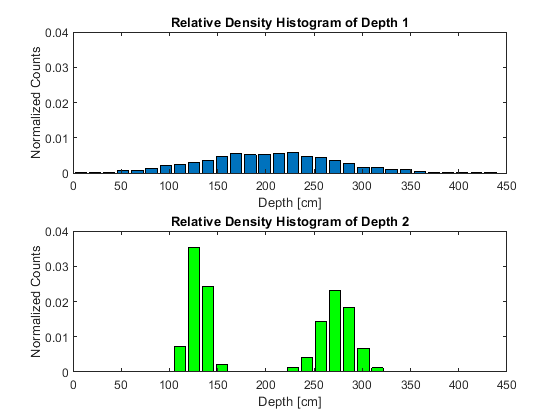

                                 
figure(4); clf                                                   % initialize and clear figure for RDH D1
subplot(2,1,1);                                                  % 1st of 2 subplots
bar(xbins, RDH_D(:,1))                                           % make bar plot of histogram of D1 - from above
title('Relative Density Histogram of Depth 1')                   % title plot
xlabel('Depth [cm]')                                             % give plot x label            
ylabel('Normalized Counts')                                      % give plot y label
hold on                                                          % allows me to plot something else on same plot
%plot(x, f_d1, 'r-', 'LineWidth', 2)                             % plot normal distribution curve
axis([0 450 0 0.04])                                             % define axis extents

subplot(2,1,2)                                                   % initialize and clear figure for RDH D2
bar(xbins, RDH_D(:,2), 'FaceColor', 'green' )                    % add bar plot of RDH d2 to figure                      % make bar plot of histogram of D2 - from above
title('Relative Density Histogram of Depth 2')                   % title plot
xlabel('Depth [cm]')                                             % give plot x label            
ylabel('Normalized Counts')                                      % give plot y label
hold on                                                          % allows me to plot something else on same plot
%plot(x, f_d2, 'r-', 'LineWidth', 2)                             % plot normal distribution curve for D2
axis([ 0 450 0 0.04])                                            % define axis extents

## 8. The Gaussian (normal) distribution has the form f(x; µ, σ2 ) = 1 σ √ 2π e − (x−µ). 2 2σ2 (1) 1 for mean µ and standard deviation σ. Using your calculated mean and standard deviation from above, calculate the normal distribution curve and plot it with a thick red line on your relative density histograms above.

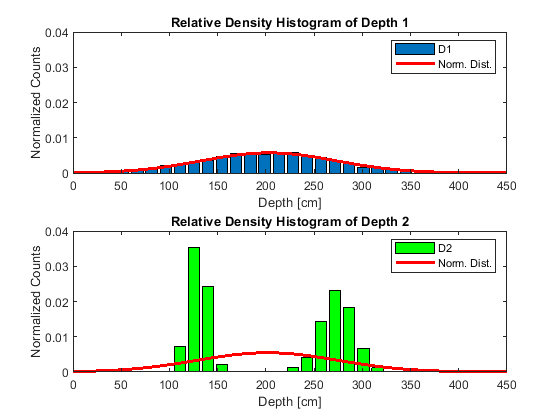

x = (0:0.1:500);                             % array to evaluate normal distribution (0-500 by 0.1)
f_d1 = mynormpdf(x, meanD(1), stdD(1));      % evaluate normal distribution for D1 using function I made (mynormpdf from HP)
f_d2 = mynormpdf(x, meanD(2), stdD(2));      % evaluate normal distribution for D1 using function (mynormpdf)

figure(5); clf                                               % initialize and clear figure for RDH D1
subplot(2,1,1);                                              % 1st of 2 subplots
bar(xbins, RDH_D(:,1))                                       % make bar plot of histogram of D1 - from above
title('Relative Density Histogram of Depth 1')               % title plot
xlabel('Depth [cm]')                                         % give plot x label            
ylabel('Normalized Counts')                                  % give plot y label
hold on                                                      % allows me to plot something else on same plot
plot(x, f_d1, 'r-', 'LineWidth', 2)                          % plot normal distribution curve
axis([0 450 0 0.04])                                         % set axes of figures to predetermined value
legend('D1', 'Norm. Dist.')                                  % add a legend

subplot(2,1,2)                                               % initialize and clear figure for RDH D2
bar(xbins, RDH_D(:,2), 'FaceColor', 'green' )                % add bar plot to figure                          % make bar plot of histogram of D2 - from above
title('Relative Density Histogram of Depth 2')               % title plot
xlabel('Depth [cm]')                                         % give plot x label            
ylabel('Normalized Counts')                                  % give plot y label
hold on                                                      % allows me to plot something else on same plot
plot(x, f_d2, 'r-', 'LineWidth', 2)                          % plot normal distribution curve for D2
axis([ 0 450 0 0.04])                                        % set axes of figures to predetermined value
legend('D2', 'Norm. Dist.')                                  % add a legend

## 9. What is the probability of a new measurement at each site being within 20cm of the average value?

%D1
P_d1 = zeros(1000,1);                % preallocate P with 100 rows, 1 column
for n = 1:1000                       % run loop from 1 to 1000
    T = randsample(D1, 1000, true);  % randomly sample out of D1 100 times with replacement
    T2 = (T > (meanD(1) - 20));      % T > 20 cm of mean
    T3 = (T < ( meanD(1) + 20));     % T < 20 cm of mean
    T4 = T2 & T3;                    % which ones are T2&T3
    P_d1(n) = sum(T4)/length(T4);    % probability of random sample being b/w mean +/- 1 std of mean --> indexed to nth iteration
end
    
meanP_d1_20 = mean(P_d1);            % average of 1000 mean values of P(mu +/- 20 cm)
fprintf('The probability of a new measurement at site 1 being within 20 cm of the average value is %.3f ', meanP_d1_20)     % print the probability

The probability of a new measurement at site 1 being within 20 cm of the average value is 0.213 


%D2
P_d2 = zeros(1000,1);               % preallocate P with 100 rows, 1 column
for n = 1:1000                      % run loop from 1 to 1000
    T = randsample(D2, 1000, true); % randomly sample out of D1 100 times with replacement
    T2 = (T > (meanD(2) - 20));     % T > 20 cm of mean
    T3 = (T < ( meanD(2) + 20));    % T < 20 cm of mean
    T4 = T2 & T3;                   % which ones are T2&T3
    P_d2(n) = sum(T4)/length(T4);   % probability of random sample being b/w mean +/- 1 std of mean --> indexed to nth iteration
end                                 % end loop
    
meanP_d2_20 = mean(P_d2);           % average of 1000 mean values of P(mu +/- 20 cm)
fprintf('The probability of a new measurement at site 2 being within 20 cm of the average value is %.3f ', meanP_d2_20)     % print the probability

The probability of a new measurement at site 2 being within 20 cm of the average value is 0.001 

## 10. What is the probability of a new measurement at each site being at least 20cm larger than the average value?

%D1
P_d1_9 = zeros(1000,1);             % preallocate P with 100 rows, 1 column
for n = 1:1000                      % run loop from 1 to 1000
    T = randsample(D1, 1000, true); % randomly sample out of D1 100 times with replacement
    T2 = (T > (meanD(1) + 20));     % T > 20 cm of mean
    T4 = T2;                        % which ones are T2&T3
    P_d1_9(n) = sum(T4)/length(T4); % probability of random sample being b/w mean +/- 1 std of mean --> indexed to nth iteration
end                                 % end loop
    
meanP_d1_9 = mean(P_d1_9);          % average of 1000 mean values of P(mu + 20 cm)
fprintf('The probability of a new measurement at site 1 being 20 cm or more greater than the average value is %.3f ', meanP_d1_9)  % print the probability

The probability of a new measurement at site 1 being 20 cm or more greater than the average value is 0.393 


%D2
P_d2_9 = zeros(1000,1);             % preallocate P with 100 rows, 1 column
for n = 1:1000                      % run loop from 1 to 1000
    T = randsample(D2, 1000, true);  % randomly sample out of D1 100 times with replacement
    T2 = (T > (meanD(2) + 20));     % T > 20 cm of mean
    T4 = T2;                        % which ones are T2&T3
    P_d2_9(n) = sum(T4)/length(T4); % probability of random sample being b/w mean +/- 1 std of mean --> indexed to nth iteration
end                                 % end loop
    
meanP_d2_9 = mean(P_d2_9);          % average of 1000 mean values of P(mu + 20 cm)
fprintf('The probability of a new measurement at site 2 being 20 cm or more greater than the average value is %.3f ', meanP_d2_9)  % print the probability

The probability of a new measurement at site 2 being 20 cm or more greater than the average value is 0.499 

## 11. What is the probability of a new measurement at each site being at least 20cm smaller than the average value?

%D1
P_d1_10 = zeros(1000,1);             % preallocate P with 100 rows, 1 column
for n = 1:1000                       % run loop from 1 to 1000
    T = randsample(D1, 1000, true);  % randomly sample out of D1 100 times with replacement
    T2 = (T < (meanD(1) - 20));      % T < 20 cm of mean
    T4 = T2;                         % which ones are T2
    P_d1_10(n) = sum(T4)/length(T4);  % probability of random sample being b/w mean +/- 1 std of mean --> indexed to nth iteration
end                                   % end loop
    
meanP_d1_10 = mean(P_d1_10);          % average of 1000 mean values of P(mu - 20 cm)
fprintf('The probability of a new measurement at site 1 being at least 20 cm smaller than the average value is %.3f ', meanP_d1_10)  % print the probability

The probability of a new measurement at site 1 being at least 20 cm smaller than the average value is 0.394 


%D2
P_d2_10 = zeros(1000,1);             % preallocate P with 100 rows, 1 column
for n = 1:1000                       % run loop from 1 to 1000
    T = randsample(D2, 1000, true);  % randomly sample out of D1 100 times with replacement
    T2 = (T < (meanD(2) - 20));      % T < 20 cm of mean
    T4 = T2;                         % which ones are T2
    P_d2_10(n) = sum(T4)/length(T4);  % probability of random sample being b/w mean +/- 1 std of mean --> indexed to nth iteration
end                                   % end for loop
    
meanP_d2_10 = mean(P_d2_10);         % average of 1000 mean values of P(mu - 20 cm)
fprintf('The probability of a new measurement at site 2 being at least 20 cm smaller than the average value is %.3f ', meanP_d2_10)     % print the probability

The probability of a new measurement at site 2 being at least 20 cm smaller than the average value is 0.499 